# Exemplo Sistema Segunda Ordem

Definição do sistema

s = tf('s');
P = 47.1/(s^2 + 5.54*s + 47.1)


P =
 
         47.1
  -------------------
  s^2 + 5.54 s + 47.1
 
Continuous-time transfer function.



Resposta ao degrau

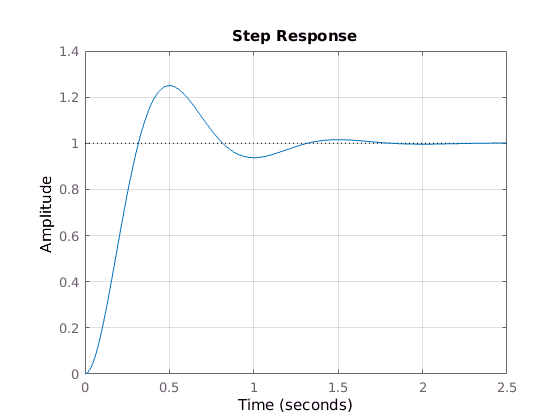

step(P)
grid on

Informações do degrau

stepinfo(P)

ans = struct with fields:
        RiseTime: 0.2143
    SettlingTime: 1.2252
     SettlingMin: 0.9375
     SettlingMax: 1.2501
       Overshoot: 25.0084
      Undershoot: 0
            Peak: 1.2501
        PeakTime: 0.4988


% Padrão do Matlab é 2%, assim como a aproximação que usamos
stepinfo(P,'SettlingTimeThreshold',0.02,'RiseTimeLimits',[0 1])

ans = struct with fields:
        RiseTime: 0.3164
    SettlingTime: 1.2252
     SettlingMin: 0.9375
     SettlingMax: 1.2501
       Overshoot: 25.0084
      Undershoot: 0
            Peak: 1.2501
        PeakTime: 0.4988


% Padrão do Matlab é de 10% a 90%. Queremos de 0 a 100%:
stepinfo(P,'RiseTimeLimits',[0 1])

ans = struct with fields:
        RiseTime: 0.3164
    SettlingTime: 1.2252
     SettlingMin: 0.9375
     SettlingMax: 1.2501
       Overshoot: 25.0084
      Undershoot: 0
            Peak: 1.2501
        PeakTime: 0.4988


Apêndice

wd = 6.28;
alpha = 2.77;
phi = atan(wd/alpha);
% Tempo de acomodação
ta = 3.912/alpha

ta = 1.4123

% Tempo de subida
ts = (pi - phi)/wd

ts = 0.3163

% Fonte: doc stepinfo
-log(0.02)

ans = 3.9120